## Post-Processing

Une fois exécutés la génération du modèle, la mise à l'échelle, la cinématique inverse et la dynamique inverse, nous allons répondre aux deux questions posées en introduction.

load BiomechanicalModel.mat
load Trial010/InverseKinematicsResults.mat

### Analyse cinématique

On regarde les angles articulaires coude/épaule pour trouver les adaptations réalisées par le sujet au cours de la fente.

**Question 5: investiguer l'erreur cinématique moyenne (RMS) et max. Est-elle acceptable ?**

%On exclut les extrémités qui peuvent subir des effets de filtrage
Mean_Error=rms(InverseKinematicsResults.ReconstructionError(25:925));
[Max_Error,idx]=max(InverseKinematicsResults.ReconstructionError(25:925));

%% TODO : tracer l'erreur moyenne et l'erreur max de reconstruction des marqueurs. Discuter le résultat

figure 
hold on
grid on
%% ajouter ici le tracé
ylabel('Reconstruction error (mm)')
xlabel('Temps (s)')

% TODO : calculer et afficher l'erreur moyenne et max sur l'essai. La
% recommandation générale est d'avoir une moyenne <20 mm et un max <40mm.
% Est ce bon ici ?


**Question 6: Investiguer le biomechanical model pour tracer le plan d'élévation de l'épaule gauche, l'élévation de l'épaule et la flexion du coude**. **Quelle adaptation a réalisé l'athlète pour "corriger" sa fente au cours de l'extension ?**

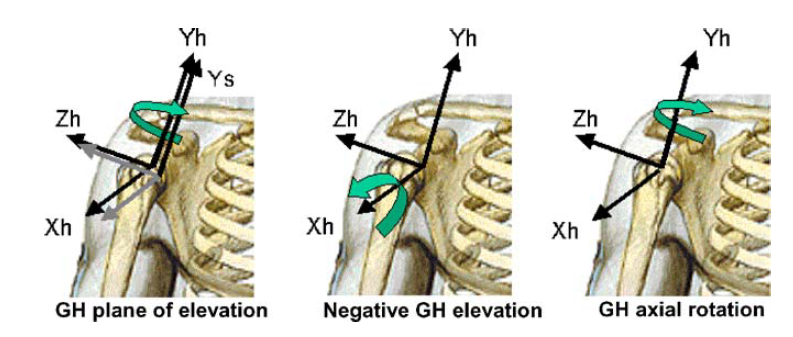

%TODO aller investiguer le biomechanical model pour trouver quelle
%coordonnée articulaire tracer

figure
hold on
grid on
%% TODO : compléter ici en modifiant 'XX'
%% plot(t_mocap,InverseKinematicsResults.JointCoordinates(XX,:)*180/pi,'LineWidth',2);

xlabel('Temps (s)')
ylabel('Angle articulaire (°)')
legend({'Shoulder Plane of Elevation','Shoulder Elevation','Elbow Flexion'})

### Analyse Dynamique

On regarde à présent le couple de flexion/extension du genou au niveau de l'appui (jambe arrière)

load Trial010/InverseDynamicsResults.mat


**Question 7 : investiguer le Biomechanical Model et trouver quel couple tracer dans le tableau InverseDynamicsResults.JointTorques.**


%TODO aller investiguer le biomechanical model pour trouver quelle
% couple tracer

%angle du genou
q=zeros(1,n_frames);%initialisation angle du genou
%q=? utiliser la structure InverseKinematicsResults

%vitesse articulaire du genou
dq=zeros(1,n_frames);
%dq= ? Réutiliser la fonction dérivée vue au dessus
%couple au genou
tau=zeros(1,n_frames);
%tau= ? utiliser la structure InverseDynamicsResults


**Question 8 : Calculer et tracer le % du couple maximal admissible au cours de la fente. Quelles conclusions porter à cette analyse ?**

% calcul du couple d'extension maximal admissible
taumax=zeros(1,n_frames);
for i=1:n_frames
taumax(i)=anderson_kneef_1825(q(i),dq(i),85.5,1.77);
end

tauper=(tau)./taumax;


figure
subplot(4,1,1)
hold on
grid on
plot(t_mocap,q*180/pi,'LineWidth',2);
xlabel('Temps (s)')
ylabel({'Angle Flexion'; 'Genou (°)'})
subplot(4,1,2)
hold on
grid on
plot(t_mocap,dq*180/pi,'LineWidth',2);
xlabel('Temps (s)')
ylabel({'Vitesse angulaire';'Flexion Genou (°/s)'})
subplot(4,1,3)
hold on
grid on
plot(t_mocap,tau,'LineWidth',2);
xlabel('Temps (s)')
ylabel({'Couple Flexion';'Genou (N.m)'})
subplot(4,1,4)
hold on
grid on
plot(t_mocap,tauper,'LineWidth',2);
xlabel('Temps (s)')
ylabel({'Couple Normalisé'; 'Flexion Genou (%)'})
